# **TENT Map**

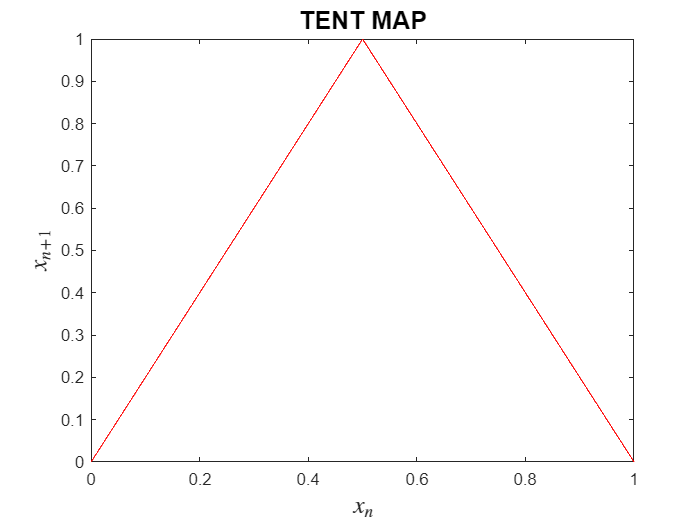

n = 100000;
x = linspace(0,1,n);
y = zeros(size(x));
for i=1:length(x)
    if x(i) < 0.5
        y(i) = 2*x(i);
    else
       y(i) = 2*(1-x(i)); 
    end
end
plot(x,y,'r');
title("TENT MAP", FontSize=15);
xlabel("$x_n$",'Interpreter','latex',FontSize=15);
ylabel("$x_{n+1}$",'Interpreter','latex',FontSize=15);

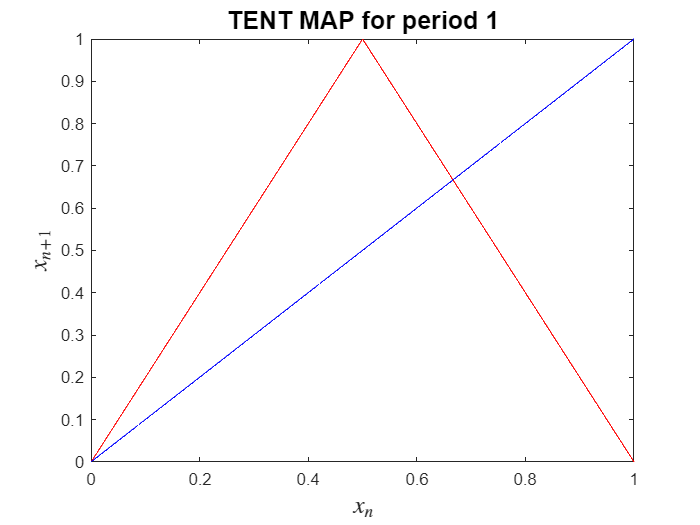

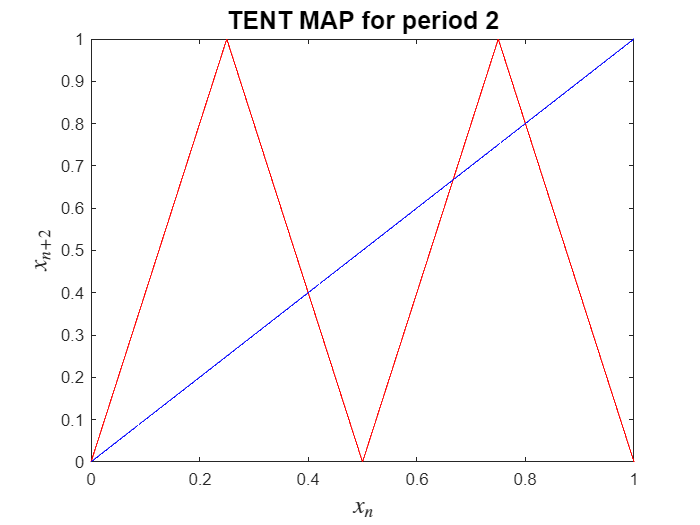

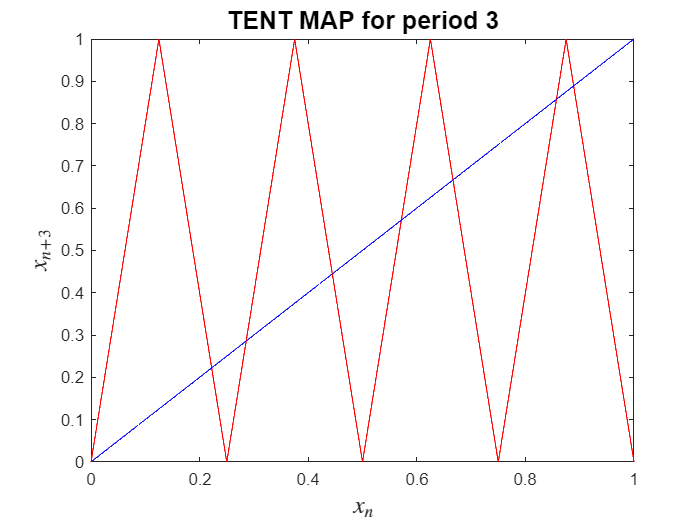

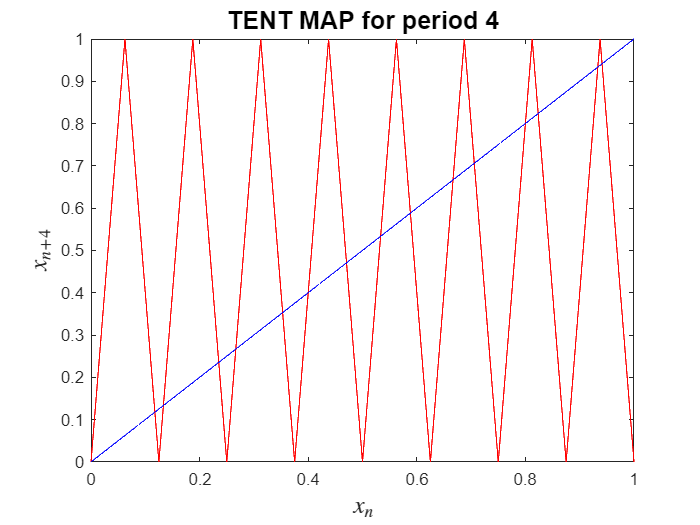

y = linspace(0,1,n);
for i=1:4
    x = linspace(0,1,n);
    for j=1:i
        for k=1:length(x)
            if x(k) < 0.5
                x(k) = 2*x(k);
            else
                x(k) = 2*(1-x(k)); 
            end
        end
    end
    figure;
    plot(y,x,'r',y,y,'b');
    title("TENT MAP for period " + i, FontSize=15);
    xlabel("$x_n$",'Interpreter','latex',FontSize=15);
    ylabel(sprintf("$x_{n+%d}$",i),'Interpreter','latex',FontSize=15);
end

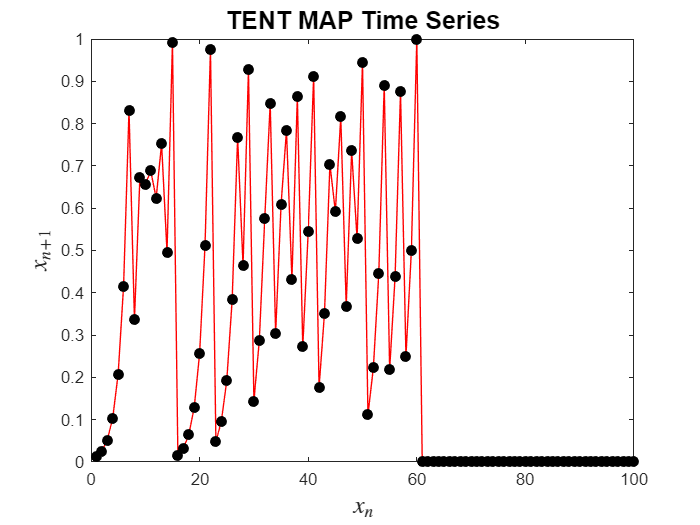

n = 100;
x = 0.013;
y = zeros(1,n);
for i=1:n
    if x < 0.5
        y(i) = x;
        x = 2*x;
    else
       y(i) = x;
       x = 2*(1-x); 
    end
end
plot(y,'r', marker='o', markerfacecolor='black', markeredgecolor='black');
title("TENT MAP Time Series", FontSize=15);
xlabel("$x_n$",'Interpreter','latex',FontSize=15);
ylabel("$x_{n+1}$",'Interpreter','latex',FontSize=15);

# **SHIFT Map**

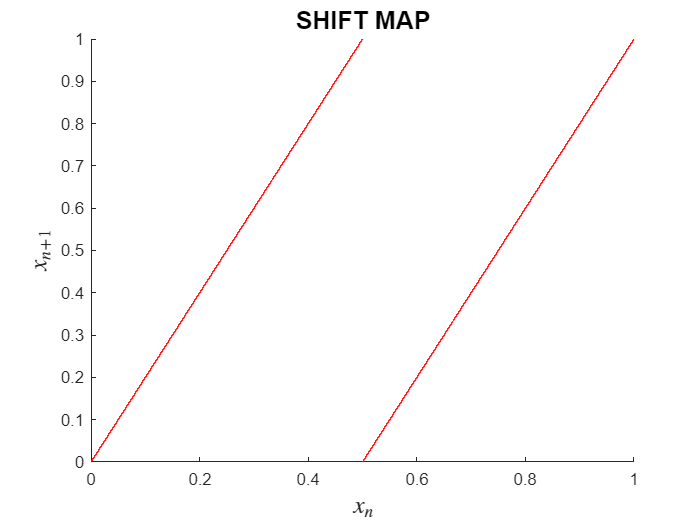

n = 100000;
x = linspace(0,1,n);
y = zeros(size(x));
for i=1:length(x)
       y(i) = mod(2*x(i),1); 
end
scatter(x,y,0.1,'r');
title("SHIFT MAP", FontSize=15);
xlabel("$x_n$",'Interpreter','latex',FontSize=15);
ylabel("$x_{n+1}$",'Interpreter','latex',FontSize=15);

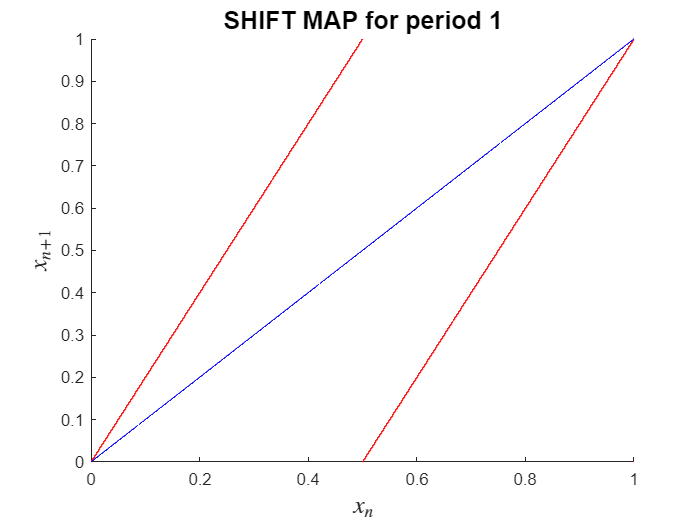

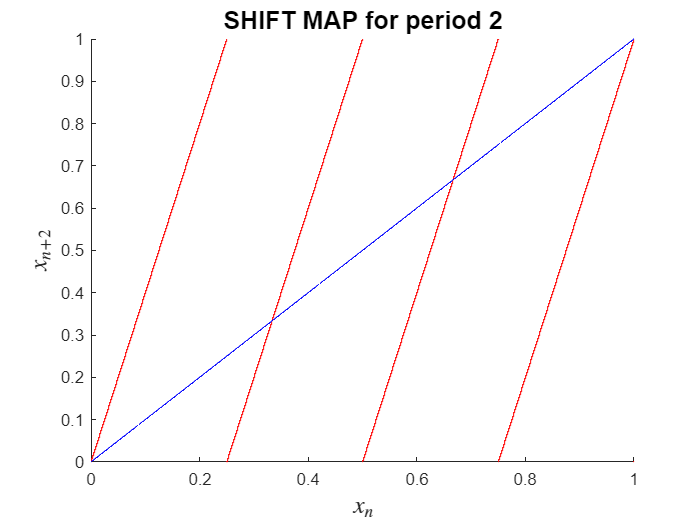

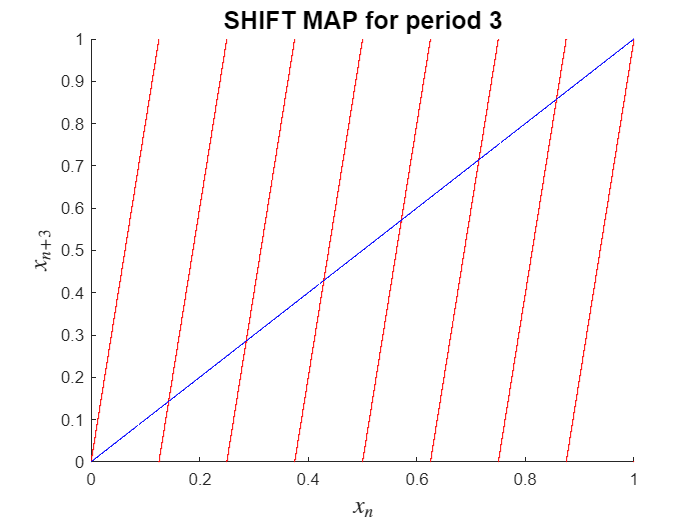

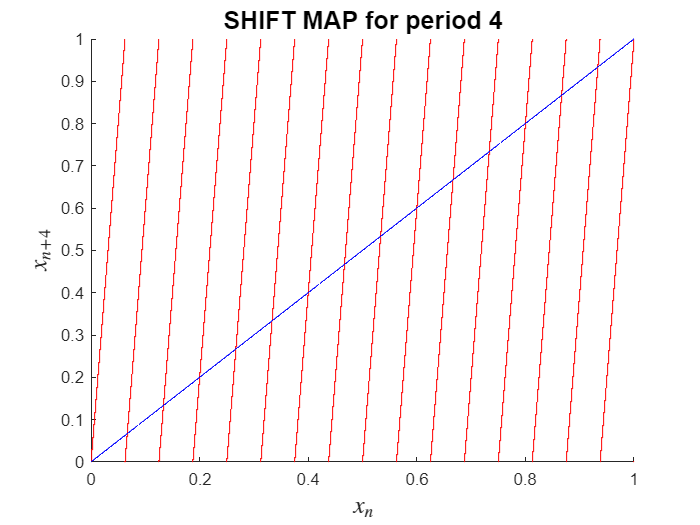

y = linspace(0,1,n);
for i=1:4
    x = linspace(0,1,n);
    for j=1:i
        for k=1:length(x)
                x(k) = mod(2*x(k),1);
        end
    end
    figure;
    scatter(y,x,0.1,'red');
    hold on
    plot(y,y,'b');
    title("SHIFT MAP for period " + i, FontSize=15);
    xlabel("$x_n$",'Interpreter','latex',FontSize=15);
    ylabel(sprintf("$x_{n+%d}$",i),'Interpreter','latex',FontSize=15);
end

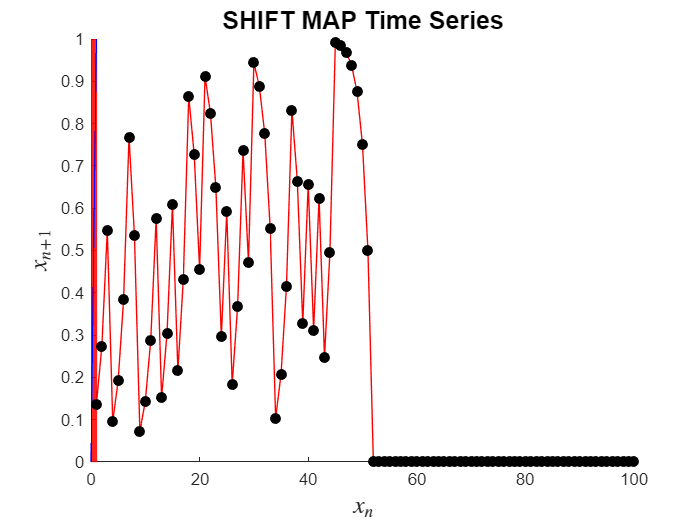

n = 100;
x = 0.137;
y = zeros(1,n);
for i=1:n
       y(i) = x; 
       x =mod(2*x,1);
end
plot(y,'r',marker='o',markerfacecolor='black', markeredgecolor='black');
title("SHIFT MAP Time Series", FontSize=15);
xlabel("$x_n$",'Interpreter','latex',FontSize=15);
ylabel("$x_{n+1}$",'Interpreter','latex',FontSize=15);